x_max = 55;
N_max_gr = 8;
gamma0 = 0;
gamma1 = 1;
gamma2 = 3;

x_eff = 11.8;
x_eff_real = 16;
psi = 0.96;
psi_real = 1.008;
A = [1.0075 1.0095 1.01]';
A_real = [1.0018 1.016 1.009]';
% I'm not going to bother writing out the group number bit since it will
% cancel with the 10
B = [1.65 2.07 2.47]';
B_real = [1.6969 2.2175 2.6709]';
lambda = 700;

x_con_init = [20 22 25 27 17]; 
x_aux_init = [6 6 7 7 8];

parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

parameters_pred = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff, ...
    'psi', psi, ...
    'A', A, ...
    'B', B, ...
    'lambda', lambda);


Np = 6;
parameters = parameters_real;

xk = [55;8];
[a,b,c] = functionForAll2(Np, xk, parameters, 0)

a =      0
     0


b = 0

c = 1000000

## 2.5) MPC

run = true;
if run
    Np = 6;
    % RUN 1 - Np = 6 - J_opt = 23805
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 60; 
    
    xk_6 = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k_6 = zeros(5,T_end+1)
    xk_6(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk_6(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k_6(j,i), ~] = finduOpt(xk_6(:,j,i-1)); 
            [xk_6(:,j,i), ~, J] = realUpdate(xk_6(:,j,i-1), u_k_6(j,i));
            total_cost = total_cost + J;
        end
    end
%{
    % RUN 2 - Np = 15 - J_opt = 23105
    Np = 15;
    finduOpt = @(xk) functionForAll2(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll2(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 60; 
    
    xk_15 = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k_15 = zeros(5,T_end+1);
    xk_15(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    total_cost = 0;
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk_15(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k_15(j,i), ~] = finduOpt(xk_15(:,j,i-1)); 
            [xk_15(:,j,i), ~, J] = realUpdate(xk_15(:,j,i-1), u_k_15(j,i));
            total_cost = total_cost + J;
        end
    end

%}
end

u_k_6 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

    "x_k = 20  22  25  27  17"
    "x_k =  6   6   7   7   8"



time_elapsed = 0.0013218seconds


time step 1 of 60


    "x_k = 21.7329      23.7365      26.7419      28.7455      18.7275"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.14684seconds


time step 2 of 60


    "x_k = 23.4689      25.4761      28.4869      30.4941      20.4581"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.29704seconds


time step 3 of 60


    "x_k = 25.2081      27.2189      30.2351      33.1995      22.1918"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.4497seconds


time step 4 of 60


    "x_k = 26.9503      28.9648      32.9364      35.9482      23.9287"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.67745seconds


time step 5 of 60


    "x_k = 28.6957      30.7138      35.6809      38.7409      25.6687"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.83789seconds


time step 6 of 60


    "x_k = 30.4443      33.4227      38.4692      41.5783      27.4118"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.0352seconds


time step 7 of 60


    "x_k = 33.1489       36.175      41.3023       44.461       29.158"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.2526seconds


time step 8 of 60


    "x_k = 35.8968      38.9713      44.1806      47.3899      30.9074"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.5071seconds


time step 9 of 60


    "x_k = 38.6886      41.8123       47.105       31.641      33.6194"
    "x_k =       6            6            7            8            8"



time_elapsed = 1.7765seconds


time step 10 of 60


    "x_k = 41.5252      44.6988      31.3538      34.3648      36.3748"
    "x_k =       6            6            8            8            8"



time_elapsed = 1.9681seconds


time step 11 of 60


    "x_k = 44.4071      28.9284       34.073      37.1321      39.1743"
    "x_k =       6            7            8            8            8"



time_elapsed = 2.1549seconds


time step 12 of 60


    "x_k = 28.6343      30.6774      36.8357      39.9437      42.0186"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.3102seconds


time step 13 of 60


    "x_k = 30.3828      33.3857      39.6425      42.8003      44.9084"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.4669seconds


time step 14 of 60


    "x_k = 33.0864      36.1374      42.4943      45.7026      47.8444"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.7145seconds


time step 15 of 60


    "x_k = 35.8333      38.9331      45.3917      48.6514      50.8274"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.8883seconds


time step 16 of 60


    "x_k = 38.6241      41.7735      48.3355      51.6473            0"
    "x_k =       7            7            8            8            0"



time_elapsed = 3.0544seconds


time step 17 of 60


    "x_k = 41.4596      44.6594      51.3263            0       1.6969"
    "x_k =       7            7            8            0            0"



time_elapsed = 3.1877seconds


time step 18 of 60


    "x_k = 44.3404      47.5915            0       1.6969      3.39685"
    "x_k =       7            7            0            0            0"



time_elapsed = 3.3067seconds


time step 19 of 60


    "x_k = 47.2674      50.5704       1.6969      3.39685      5.09987"
    "x_k =       7            7            0            0            0"



time_elapsed = 3.4441seconds


time step 20 of 60


    "x_k = 31.5175       34.847      3.39685      5.09987      6.80595"
    "x_k =       8            8            0            0            0"



time_elapsed = 3.5834seconds


time step 21 of 60


    "x_k = 34.2393       37.622      5.09987      6.80595       8.5151"
    "x_k =       8            8            0            0            0"



time_elapsed = 3.722seconds


time step 22 of 60


    "x_k = 37.0046      40.4415      6.80595       8.5151      10.2273"
    "x_k =       8            8            0            0            0"



time_elapsed = 3.8261seconds


time step 23 of 60


    "x_k = 39.8142      43.3061       8.5151      10.2273      11.9426"
    "x_k =       8            8            0            0            0"



time_elapsed = 3.9424seconds


time step 24 of 60


    "x_k = 42.6687      46.2165      10.2273      11.9426       13.661"
    "x_k =       8            8            0            0            0"



time_elapsed = 4.0376seconds


time step 25 of 60


    "x_k = 45.5689      49.1734      11.9426       13.661      15.3825"
    "x_k =       8            8            0            0            0"



time_elapsed = 4.1497seconds


time step 26 of 60


    "x_k = 48.5155            0       13.661      15.3825      17.1071"
    "x_k =       8            0            0            0            0"



time_elapsed = 4.2259seconds


time step 27 of 60


    "x_k = 51.5093       1.6969      15.3825      17.1071      18.8348"
    "x_k =       8            0            0            0            0"



time_elapsed = 4.2943seconds


time step 28 of 60


    "x_k = 0      3.39685      17.1071      18.8348      20.5656"
    "x_k = 0            0            0            0            0"



time_elapsed = 4.3575seconds


time step 29 of 60


    "x_k = 1.6969      5.09987      18.8348      20.5656      22.2995"
    "x_k =      0            0            0            0            0"



time_elapsed = 4.4261seconds


time step 30 of 60


    "x_k = 3.39685      6.80595      20.5656      22.2995      24.0366"
    "x_k =       0            0            0            0            0"



time_elapsed = 4.4891seconds


time step 31 of 60


    "x_k = 5.09987       8.5151      22.2995      24.0366      25.7767"
    "x_k =       0            0            0            0            0"



time_elapsed = 4.5877seconds


time step 32 of 60


    "x_k = 6.80595      10.2273      24.0366      25.7767        27.52"
    "x_k =       0            0            0            0            0"



time_elapsed = 4.7067seconds


time step 33 of 60


    "x_k = 8.5151      11.9426      25.7767        27.52      29.2665"
    "x_k =      0            0            0            0            0"



time_elapsed = 4.8211seconds


time step 34 of 60


    "x_k = 10.2273       13.661        27.52      29.2665       31.016"
    "x_k =       0            0            0            0            0"



time_elapsed = 4.9276seconds


time step 35 of 60


    "x_k = 11.9426      15.3825      29.2665       31.016      33.7298"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.0208seconds


time step 36 of 60


    "x_k = 13.661      17.1071       31.016      33.7298       36.487"
    "x_k =      0            0            0            0            0"



time_elapsed = 5.1292seconds


time step 37 of 60


    "x_k = 15.3825      18.8348      33.7298       36.487      39.2883"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.2386seconds


time step 38 of 60


    "x_k = 17.1071      20.5656       36.487      39.2883      42.1344"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.3793seconds


time step 39 of 60


    "x_k = 18.8348      22.2995      39.2883      42.1344       45.026"
    "x_k =       0            0            0            0            0"



time_elapsed = 5.4946seconds


time step 40 of 60


    "x_k = 20.5656      24.0366      42.1344       45.026      29.2582"
    "x_k =       0            0            0            0            1"



time_elapsed = 5.6105seconds


time step 41 of 60


    "x_k = 22.2995      25.7767       45.026      29.2582      31.0078"
    "x_k =       0            0            0            1            1"



time_elapsed = 5.7292seconds


time step 42 of 60


    "x_k = 24.0366        27.52      29.2582      31.0078      33.7214"
    "x_k =       0            0            1            1            1"



time_elapsed = 5.8815seconds


time step 43 of 60


    "x_k = 25.7767      29.2665      31.0078      33.7214      36.4785"
    "x_k =       0            0            1            1            1"



time_elapsed = 6.0644seconds


time step 44 of 60


    "x_k = 27.52       31.016      33.7214      36.4785      39.2796"
    "x_k =     0            0            1            1            1"



time_elapsed = 6.2178seconds


time step 45 of 60


    "x_k = 29.2665      33.7298      36.4785      39.2796      42.1256"
    "x_k =       0            0            1            1            1"



time_elapsed = 6.3697seconds


time step 46 of 60


    "x_k = 31.016       36.487      39.2796      42.1256      45.0171"
    "x_k =      0            0            1            1            1"



time_elapsed = 6.55seconds


time step 47 of 60


    "x_k = 33.7298      39.2883      42.1256      45.0171      29.2492"
    "x_k =       0            0            1            1            2"



time_elapsed = 6.7335seconds


time step 48 of 60


    "x_k = 36.487      42.1344      45.0171      29.2492      30.9988"
    "x_k =      0            0            1            2            2"



time_elapsed = 6.9037seconds


time step 49 of 60


    "x_k = 39.2883       45.026      29.2492      30.9988      33.7123"
    "x_k =       0            0            2            2            2"



time_elapsed = 7.0475seconds


time step 50 of 60


    "x_k = 42.1344      29.2582      30.9988      33.7123      36.4692"
    "x_k =       0            1            2            2            2"



time_elapsed = 7.2178seconds


time step 51 of 60


    "x_k = 45.026      31.0078      33.7123      36.4692      39.2702"
    "x_k =      0            1            2            2            2"



time_elapsed = 7.4031seconds


time step 52 of 60


    "x_k = 29.2582      33.7214      36.4692      39.2702       42.116"
    "x_k =       1            1            2            2            2"



time_elapsed = 7.5872seconds


time step 53 of 60


    "x_k = 31.0078      36.4785      39.2702       42.116      45.0074"
    "x_k =       1            1            2            2            2"



time_elapsed = 7.7762seconds


time step 54 of 60


    "x_k = 33.7214      39.2796       42.116      45.0074      29.2394"
    "x_k =       1            1            2            2            3"



time_elapsed = 7.9768seconds


time step 55 of 60


    "x_k = 36.4785      42.1256      45.0074      29.2394      30.9889"
    "x_k =       1            1            2            3            3"



time_elapsed = 8.1649seconds


time step 56 of 60


    "x_k = 39.2796      45.0171      29.2394      30.9889      33.7023"
    "x_k =       1            1            3            3            3"



time_elapsed = 8.348seconds


time step 57 of 60


    "x_k = 42.1256      29.2492      30.9889      33.7023       36.459"
    "x_k =       1            2            3            3            3"



time_elapsed = 8.5792seconds


time step 58 of 60


    "x_k = 45.0171      30.9988      33.7023       36.459      39.2599"
    "x_k =       1            2            3            3            3"



time_elapsed = 8.794seconds


time step 59 of 60


    "x_k = 29.2492      33.7123       36.459      39.2599      42.1055"
    "x_k =       2            2            3            3            3"



time_elapsed = 8.9724seconds


time step 60 of 60


## 2.5a) Plotting data

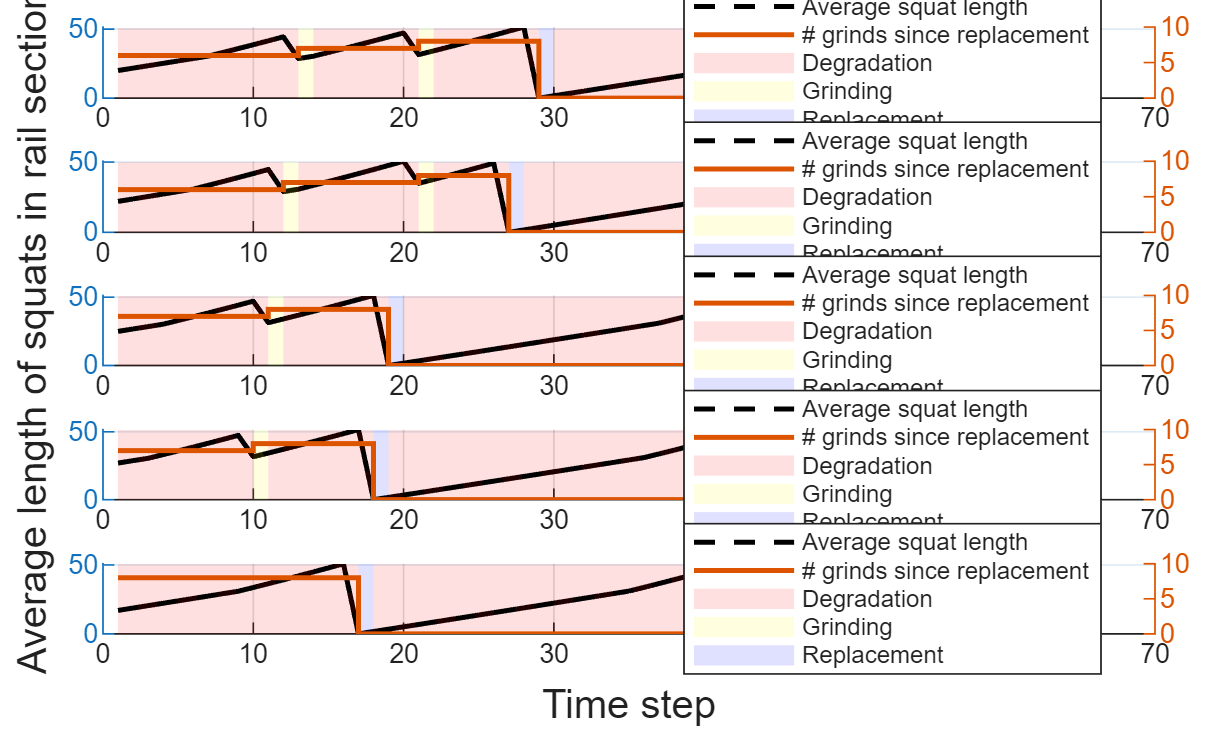

T_end = 60;
t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')
xk = xk_6; u_k = u_k_6;

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## FOr Np = 15

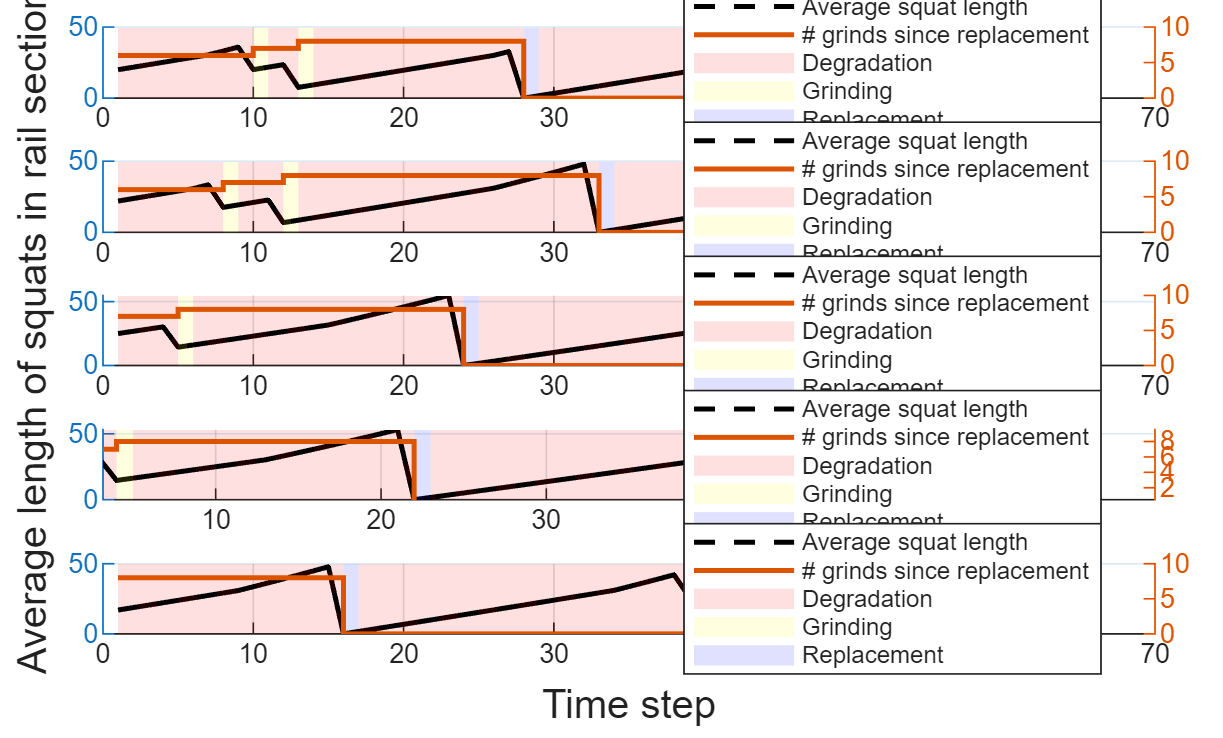

t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')

xk = xk_15; u_k = u_k_15;

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## 2.6) Regular intervention (Genetic Algorithm)

function totalCost = doMe(var)
    x_max = 55;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [20;0];
    Np = 1;
    T_end = M*(N_gr+1); 
    u = zeros(1,T_end);
    grind_IDs = M:M:T_end; u(grind_IDs) = 1;
    replacement_IDs = M*(N_gr+1):M*(N_gr+1):T_end; u(replacement_IDs) = 2;
    totalCost = 0;
    for i = 1:T_end
        [xk,~,J] = functionForAll2(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
    end 
    totalCost = totalCost/T_end;
end

run2 = true;
if run2

    tic
    LB = [1,1]; UB = [8, 40];
    doMeNow = @doMe;
    N_M = ga(doMeNow, 2, zeros(1,2), 0, zeros(1,2) ,0, LB, UB, [], [1 2]); % [8; 9], 30 mins
    N_gr_opt = N_M(1);
    M = N_M(2);
    time = toc;

end

ga stopped because the average change in the penalty function value is less than options.FunctionTolerance and 
the constraint violation is less than options.ConstraintTolerance.


## 2.6a) Single run (once parameters established above)

function [x, us, totalCost] = doMe2(var, x0)
    x_max = 55;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = x0;
    Np = 1;
    T_end = M*(N_gr+1); 
    % Setup input sequence
    u = zeros(1,T_end);
    grind_IDs = M:M:T_end; u(grind_IDs) = 1;
    replacement_IDs = M*(N_gr+1):M*(N_gr+1):T_end; u(replacement_IDs) = 2;
    totalCost = 0;
    x = zeros(2,T_end);
    us = zeros(1,T_end);
    for i = 1:T_end
        [xk,u_current,J] = functionForAll2(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        x(:,i) = xk; us(i) = u_current;
    end 
    totalCost = totalCost/T_end;
end
x0 = [0;0];

[xs, us, J] = doMe2([8;9], x0)

xs =     1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610         0    1.6969    3.3969    5.0999    6.8059    8.5151
         0         0         0         0         0         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    5.0000    5.0000    5.0000    5.0000    5.0000    

us =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     1     0     0     0     0     0


J = 95.0741

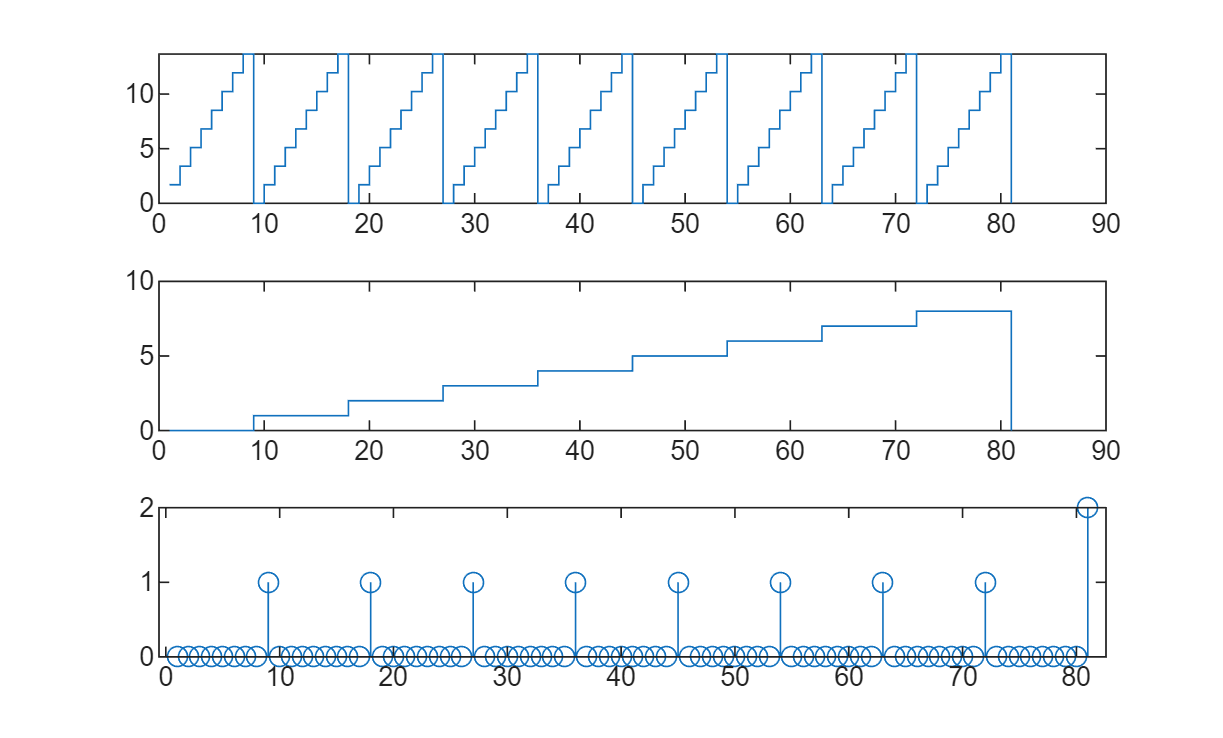


N = size(xs,2);
tiledlayout(3,1)
nexttile
stairs(1:N, xs(1,:));
nexttile
stairs(1:N, xs(2,:));
nexttile
stem(1:N, us(:));